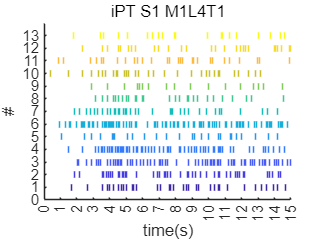

%绘制iPT和iAP 
l=4; t=1;
filepath='Z:\data\24-08-29iEMG-US-sEMG联合采集_程瑞佳\';
% eaf_name=[ 'Z:\Result\24-10-12iEMG-sEMG\M' num2str(l) 'L1T' num2str(t) '.eaf'];
% iemg_name=[ 'Z:\data\24-10-12iEMG-sEMG\M' num2str(l) 'L1T' num2str(t) '.mat'];

eaf_name=['Z:\data\24-6-21iEMG-US-sEMG联合采集_康亦铭右肱二头\signal\iEMG_US肌电后处理\iEMG_S1_M1_level' num2str(l) '_trial' num2str(t) '_24-06-21_UUS.eaf'];
iemg_name=['Z:\data\24-6-21iEMG-US-sEMG联合采集_康亦铭右肱二头\signal\iEMG_US肌电后处理\iEMG_S1_M1_level' num2str(l) '_trial' num2str(t) '_24-06-21_UUS.mat'];

% eaf_name=['Z:\data\24-6-21iEMG-US-sEMG联合采集_康亦铭右肱二头\signal\iEMG_sEMG_US肌电后处理\iEMG_HDsEMG_S1_M2_level' num2str(l) '_trial' num2str(t) '_24-06-21_UUS.eaf'];
% iemg_name=['Z:\data\24-6-21iEMG-US-sEMG联合采集_康亦铭右肱二头\signal\iEMG_sEMG_US肌电后处理\iEMG_HDsEMG_S1_M2_level' num2str(l) '_trial' num2str(t) '_24-06-21_UUS.mat'];

            % eaffile = ['Z:\data\24-6-21iEMG-US-sEMG联合采集_康亦铭右肱二头\signal\iEMG_US肌电后处理\'                 'iEMG_S1_M' num2str(M) '_level' num2str(L) '_trial' num2str(T) '_24-06-21_UUS.eaf'];%iPT
% load('Z:\Result\24-08-22iEMG-US-sEMG联合采集__胡康生右肱二头肌\822_HKS_xEMG_CBSS_decomp.mat')
% load('Z:\Result\24-08-29iEMG-US-sEMG联合采集_程瑞佳\829_xEMG_CKC_decomp_filtfilt.mat')

%绘制放电串
iEMG=importdata(iemg_name);
iEMGcell{1}=double(iEMG.Data{1});
fsampi=10240;
iPulses=eaf2pulse(eaf_name,fsampi);
iPT=draw_PluseTime(iPulses,fsampi);
title(['iPT S1 M1L' num2str(l) 'T' num2str(t)])


saveflag=false;
if(saveflag)
savefile=['Z:\Result\肱二头肌针刺双超声STA\24-6-21iEMG-US-sEMG联合采集_康亦铭右肱二头\actdraw\M1_80-128_1-128\形成区域'];
saveas(gcf,[savefile '\iPT M1L' num2str(l) 'T' num2str(t) '.png'] )
end

munumber=14;
muapi=muapExtraction(iEMGcell,iPulses,100,'STA');
clf;
plotArrayPotential(muapi{munumber},1,1);

索引超过数组元素的数量。索引不能超过 13。

title(['iAP S1 M1 L' num2str(l) ' T' num2str(t)  ' #' num2str(munumber)])
if(saveflag)
saveas(gcf,[savefile '\iAP M1L' num2str(l) ' T' num2str(t)  ' #' num2str(munumber) '.png'] )
end